# Chapter 3 ATAP Exercises

## Chebyshev Polynomials and Series

#### Mason Mault June 2025

Exercises worked

Exercise 3.2: A Chebyshev coefficient

Exercise 3.5 Chebyshev series of a complicated function

Exercise 3.8: Conditioning of the Chebyshev basis

Exercise 3.11: A function neither even nor odd

**Exercise 3.2: A Chebyshev coefficient**

Use Chebfun to numerically determine the T5 coefficient in the Chebyshev expansion of $\textrm{atan}\left(x\right)$ on [-1,1]

x = chebfun('x');
func = atan(x);
coefs = chebcoeffs(func);
TFiveCoef = coefs(6)

TFiveCoef = 0.0049

**Exercise 3.5 Chebyshev series of a complicated function**

Build chebfuns of 3 increasingly complicated functions and investigate their coefficients


$$\begin{array}{l}
f\left(x\right)=\tanh \left(x\right)\\
g\left(x\right)={10}^{-5} \tanh \left(10x\right)\\
h\left(x\right)={10}^{-10} \tanh \left(100x\right)
\end{array}$$


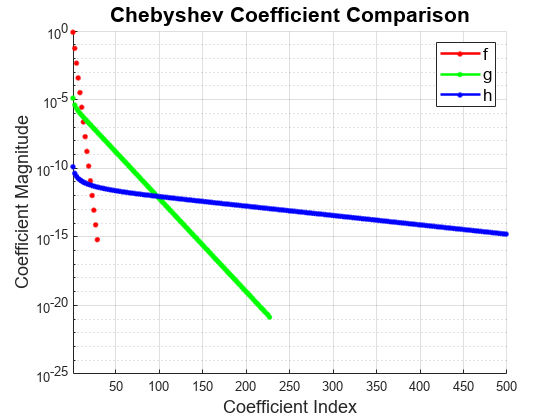

f = tanh(x);
g = 1e-5*tanh(10*x);
h = 1e-10*tanh(100*x);

figure
hold on

plotcoeffs(f, '.-r', 'LineWidth', 1.8, 'MarkerSize', 12)
plotcoeffs(g, '.-g', 'LineWidth', 1.8, 'MarkerSize', 12)
plotcoeffs(h, '.-b', 'LineWidth', 1.8, 'MarkerSize', 12)

title('Chebyshev Coefficient Comparison', 'FontSize', 16)
xlabel('Coefficient Index', 'FontSize', 14)
ylabel('Coefficient Magnitude', 'FontSize', 14)
legend({'f', 'g', 'h'}, 'FontSize', 13, 'Location', 'northeast')
grid on
set(gca, 'YScale', 'log')
xlim([1, 500]) 

As the difficulty of a function increases, so does the amount of interpolating coefficients needed to properly resolve it.

Repeat the coefficient investigation for a function defined as the sum of the three functions

$s\left(x\right)=f\left(x\right)+g\left(x\right)+h\left(x\right)=\;$$\tanh \left(x\right)$ + ${10}^{-5} \tanh \left(10x\right)$ + ${10}^{-10} \tanh \left(100x\right)$

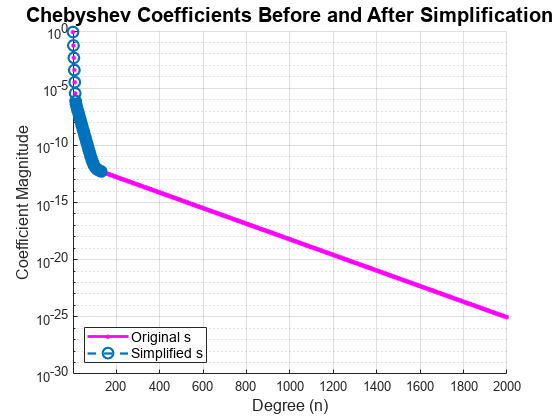

s = f + g + h;

figure
hold on

plotcoeffs(s, '.-m', 'LineWidth', 2, 'MarkerSize', 10)
plotcoeffs(simplify(s), 'o--k', 'LineWidth', 1.6, 'MarkerSize', 8)

title('Chebyshev Coefficients Before and After Simplification', 'FontSize', 15)
xlabel('Degree (n)', 'FontSize', 12)
ylabel('Coefficient Magnitude', 'FontSize', 12)
legend({'Original s', 'Simplified s'}, 'FontSize', 11, 'Location', 'southwest')

grid on
set(gca, 'YScale', 'log')
xlim([1, 2000])

The simplify command truncates the polynomial when its coefficient is roughly 1e-12, taking the 

amount of coefficients from roughly 2250 to 130.

**Exercise 3.8: Conditioning of the Chebyshev basis**

Build and investigate the "Chebfun quasimatrix" T, which will consist of the first 11 Chebyshev polynomials

T = chebpoly(0:10);
size(T)

ans =    Inf    11


svd(T)

ans =     1.5238
    1.2268
    1.2253
    1.1458
    1.1415
    1.0049
    0.9983
    0.7874
    0.7826
    0.4146


% equivalent way to grab condition number is 
% svdT(1)/svdT(end)
cond(T)

ans = 3.7126

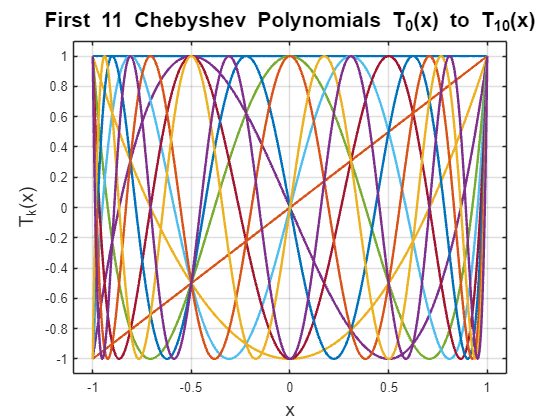

figure
plot(T, 'LineWidth', 1.8)

title('First 11 Chebyshev Polynomials T_0(x) to T_{10}(x)', 'FontSize', 16)
xlabel('x', 'FontSize', 14)
ylabel('T_k(x)', 'FontSize', 14)

grid on
xlim([-1.1, 1.1])
ylim([-1.1, 1.1])

T, the Chebyshev quasimatrix, seems like a convienient way of packaging the first n Chebyshev polynomials. Ts condition number is well behaved.

Seems fair to say each column of T is a basis vector/function. 

Construct the corresponding quasimatric for monomials on [-1, 1]

M = T;
for j = 0:10
    M(:, j + 1) = x^j;
end

cond(M)

ans = 3.0730e+03

For the same degree, the monomial quasimatrix condition number is roughly three order of magnitude larger than that of the corresponding Chebyshev quasimatrix.

Compute the condition number for M and T vs degree of polynomial from 0 to 10

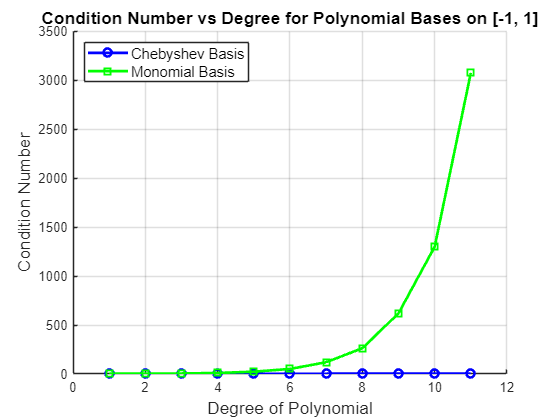

condT2 = zeros(1, 11);
condM2 = zeros(1, 11);
M2 = T;

for k = 0:10
    T2 = chebpoly(0:k);
    condT2(k + 1) = cond(T2);
    
    for i = 0:k
        M2(:, i + 1) = x^i;
    end
    
    condM2(k + 1) = cond(M2);
end

figure
hold on

semilogy(condT2, '-ob', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Chebyshev Basis')
semilogy(condM2, '-sg', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Monomial Basis')

xlabel('Degree of Polynomial', 'FontSize', 13)
ylabel('Condition Number', 'FontSize', 13)
title('Condition Number vs Degree for Polynomial Bases on [-1, 1]', 'FontSize', 13)

legend('Location', 'northwest', 'FontSize', 11)
grid on

The condition number for the monomial basis grows rapidly when compared the the Chebyshev.

Redo this condition number vs degree comparison, where M is constructed on [0, 1].

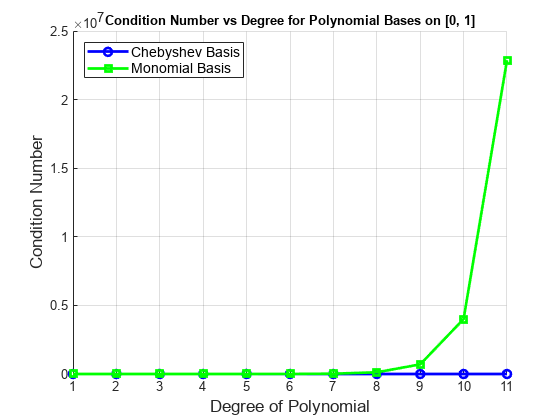

x3 = chebfun('x', [0 1]);
condT3 = zeros(1, 11);
condM3 = zeros(1, 11);
M3 = T;

for k = 0:10
    T3 = chebpoly(0:k, [0 1]);
    condT3(k + 1) = cond(T3);
    
    % fresh M3 for each k
    M3 = chebfun(zeros(length(x3), k + 1), [0 1]);

    for i = 0:k
        M3(:, i + 1) = x3^i;
    end
    
    condM3(k + 1) = cond(M3);
end

figure
hold on

semilogy(condT3, '-ob', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Chebyshev Basis')
semilogy(condM3, '-sg', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Monomial Basis')
%semilogy(condT2, '-or', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', 'Chebyshev Basis')

xlabel('Degree of Polynomial', 'FontSize', 13)
ylabel('Condition Number', 'FontSize', 13)
title('Condition Number vs Degree for Polynomial Bases on [0, 1]', 'FontSize', 10)

legend('Location', 'northwest', 'FontSize', 11)
grid on

The monomial basis condition number grows even more rapidly when defined on [-1, 1], while the Chebyshev condition number sees no change.

**Exercise 3.11: A function neither even nor odd**

Investigate the coefficients of the following function and explore why it has the appearance of a stripe.


$$\textrm{func2}\left(x\right)=\exp \left(x\right)\;/\;\left(1+10000x^2 \right)$$


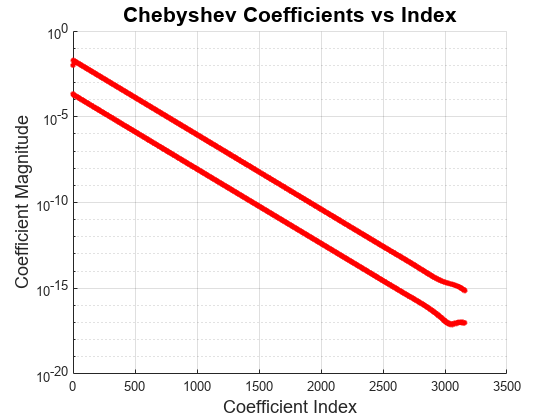

func2 = exp(x) ./ (1 + 10000*x.^2);

figure
hold on

plotcoeffs(func2, '.r', 'LineWidth', 1.8, 'MarkerSize', 12)


title('Chebyshev Coefficients vs Index', 'FontSize', 16)
xlabel('Coefficient Index', 'FontSize', 14)
ylabel('Coefficient Magnitude', 'FontSize', 14)
grid on
set(gca, 'YScale', 'log')

The top of the "stripe" in the coefficient plot corresponds to even grid points, the bottom stipe to odd.

Plot the function to help understand the stripe

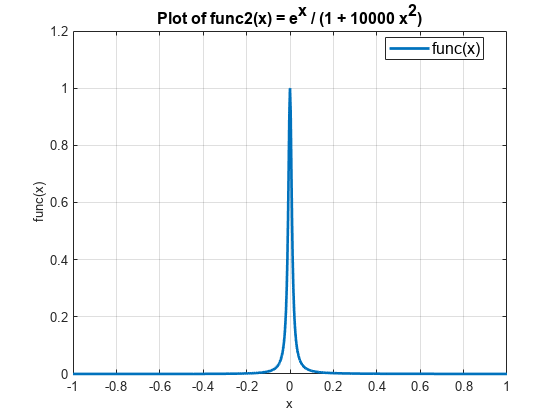

figure
plot(func2, 'LineWidth', 2)

title('Plot of func2(x) = e^x / (1 + 10000 x^2)', 'FontSize', 12)
xlabel('x', 'FontSize', 10)
ylabel('func(x)', 'FontSize', 10)

grid on
xlim([-1, 1])

legend('func(x)', 'Location', 'best', 'FontSize', 12)

 The function $f\left(x\right)=\exp \left(x\right)\;/\;\left(1+10000x^2 \right)$ as shown above is neither even nor odd, but is closer to even than odd. This explains the coefficient stripe. The even coefficients have a stronger weight, but the odd coefficients are nonzero, so the coefficients oscillate between the top and bottom branch of the stripe, decaying at similar (if not the same) rate.